# Burst photography example

Burst photography -- the combining of a burst of image captures to create a single output photograph -- has become common. Historically, the most common technique has been combining different exposure captures to allow for improved dynamic range. More recently, there has been a lot of interest in using captures with the same "under-exposure." This interest has been fueled by [Google's research into the topic](https://research.google/pubs/pub45586/).

In this Tutorial, we provide examples of combining multiple exposures of the same duration in ISETCam. Our examples are relatively simple because there is no motion in the scene. For general burst photography, objects (and the camera) move and the full algorithm has to include alignment code.

Wandell, 2019

Livescript conversion & burst comparisons, Cardinal, 2020

See also sensorComputeMEV, t_sensorMultipleExposure

ieInit
wbState = ieSessionGet('waitbar');
ieSessionSet('waitbar',false);  % Dealing with a waitbar/Matlab issue.

## Set up a scene and optical image (oi)

We can use an HDR scene or an RGB image. Using an HDR scene helps show the potential advantage of burst photography in capturing high-dynamic-range scenes by using multiple frames. Using an RGB image like the MCC provides a helpful tool in evaluating noise levels and image quality. 

hdrScene =true% Use an HDR scene

hdrScene = logical
   1


Reading multispectral data with mcCOEF.
Saved using svd method


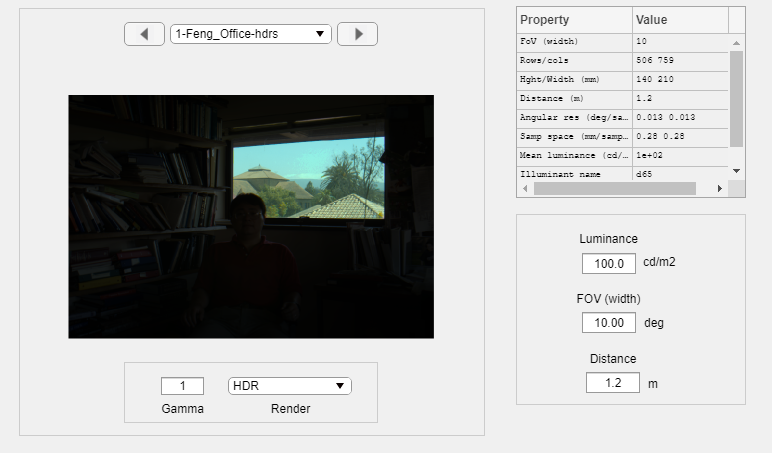

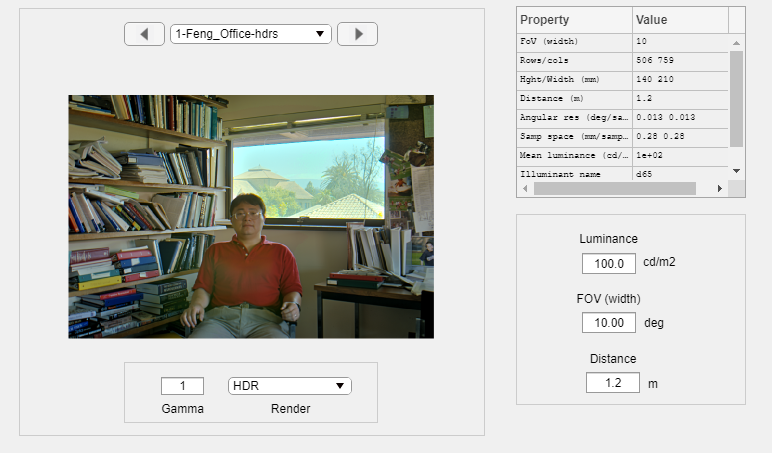

if hdrScene
    scene = sceneFromFile('Feng_Office-hdrs.mat','multispectral'); %#ok<UNRCH>
    sceneWindow(scene); sceneSet(scene,'display mode','hdr');
else
    scene = sceneCreate; %#ok<UNRCH> % for the default MCC
end


% create an optical image of our scene with the default optics
oi = oiCreate; oi = oiCompute(oi,scene);

## Run the sensor simulations

### First in auto exposure mode.  

This works okay for the MCC, but not so well for the HDR scene, as the sensor can't capture the full range of the scene at once.

% Create a default sensor and set it to our scene FOV
sensor = sensorCreate; 
sensor = sensorSet(sensor,'fov',sceneGet(scene,'fov'),oi);

sensorAE = sensorSet(sensor,'name','Single-frame, Auto exposure');
sensorAE = sensorSet(sensorAE,'noise flag','default'); 
sensorAE = sensorCompute(sensorAE,oi);

Line is (x,y), not row,col.  (1,1) is upper left corner. 

The bright region is the window in the image.

showLine      = 80% Pick the row of the image to plot

showLine = 80

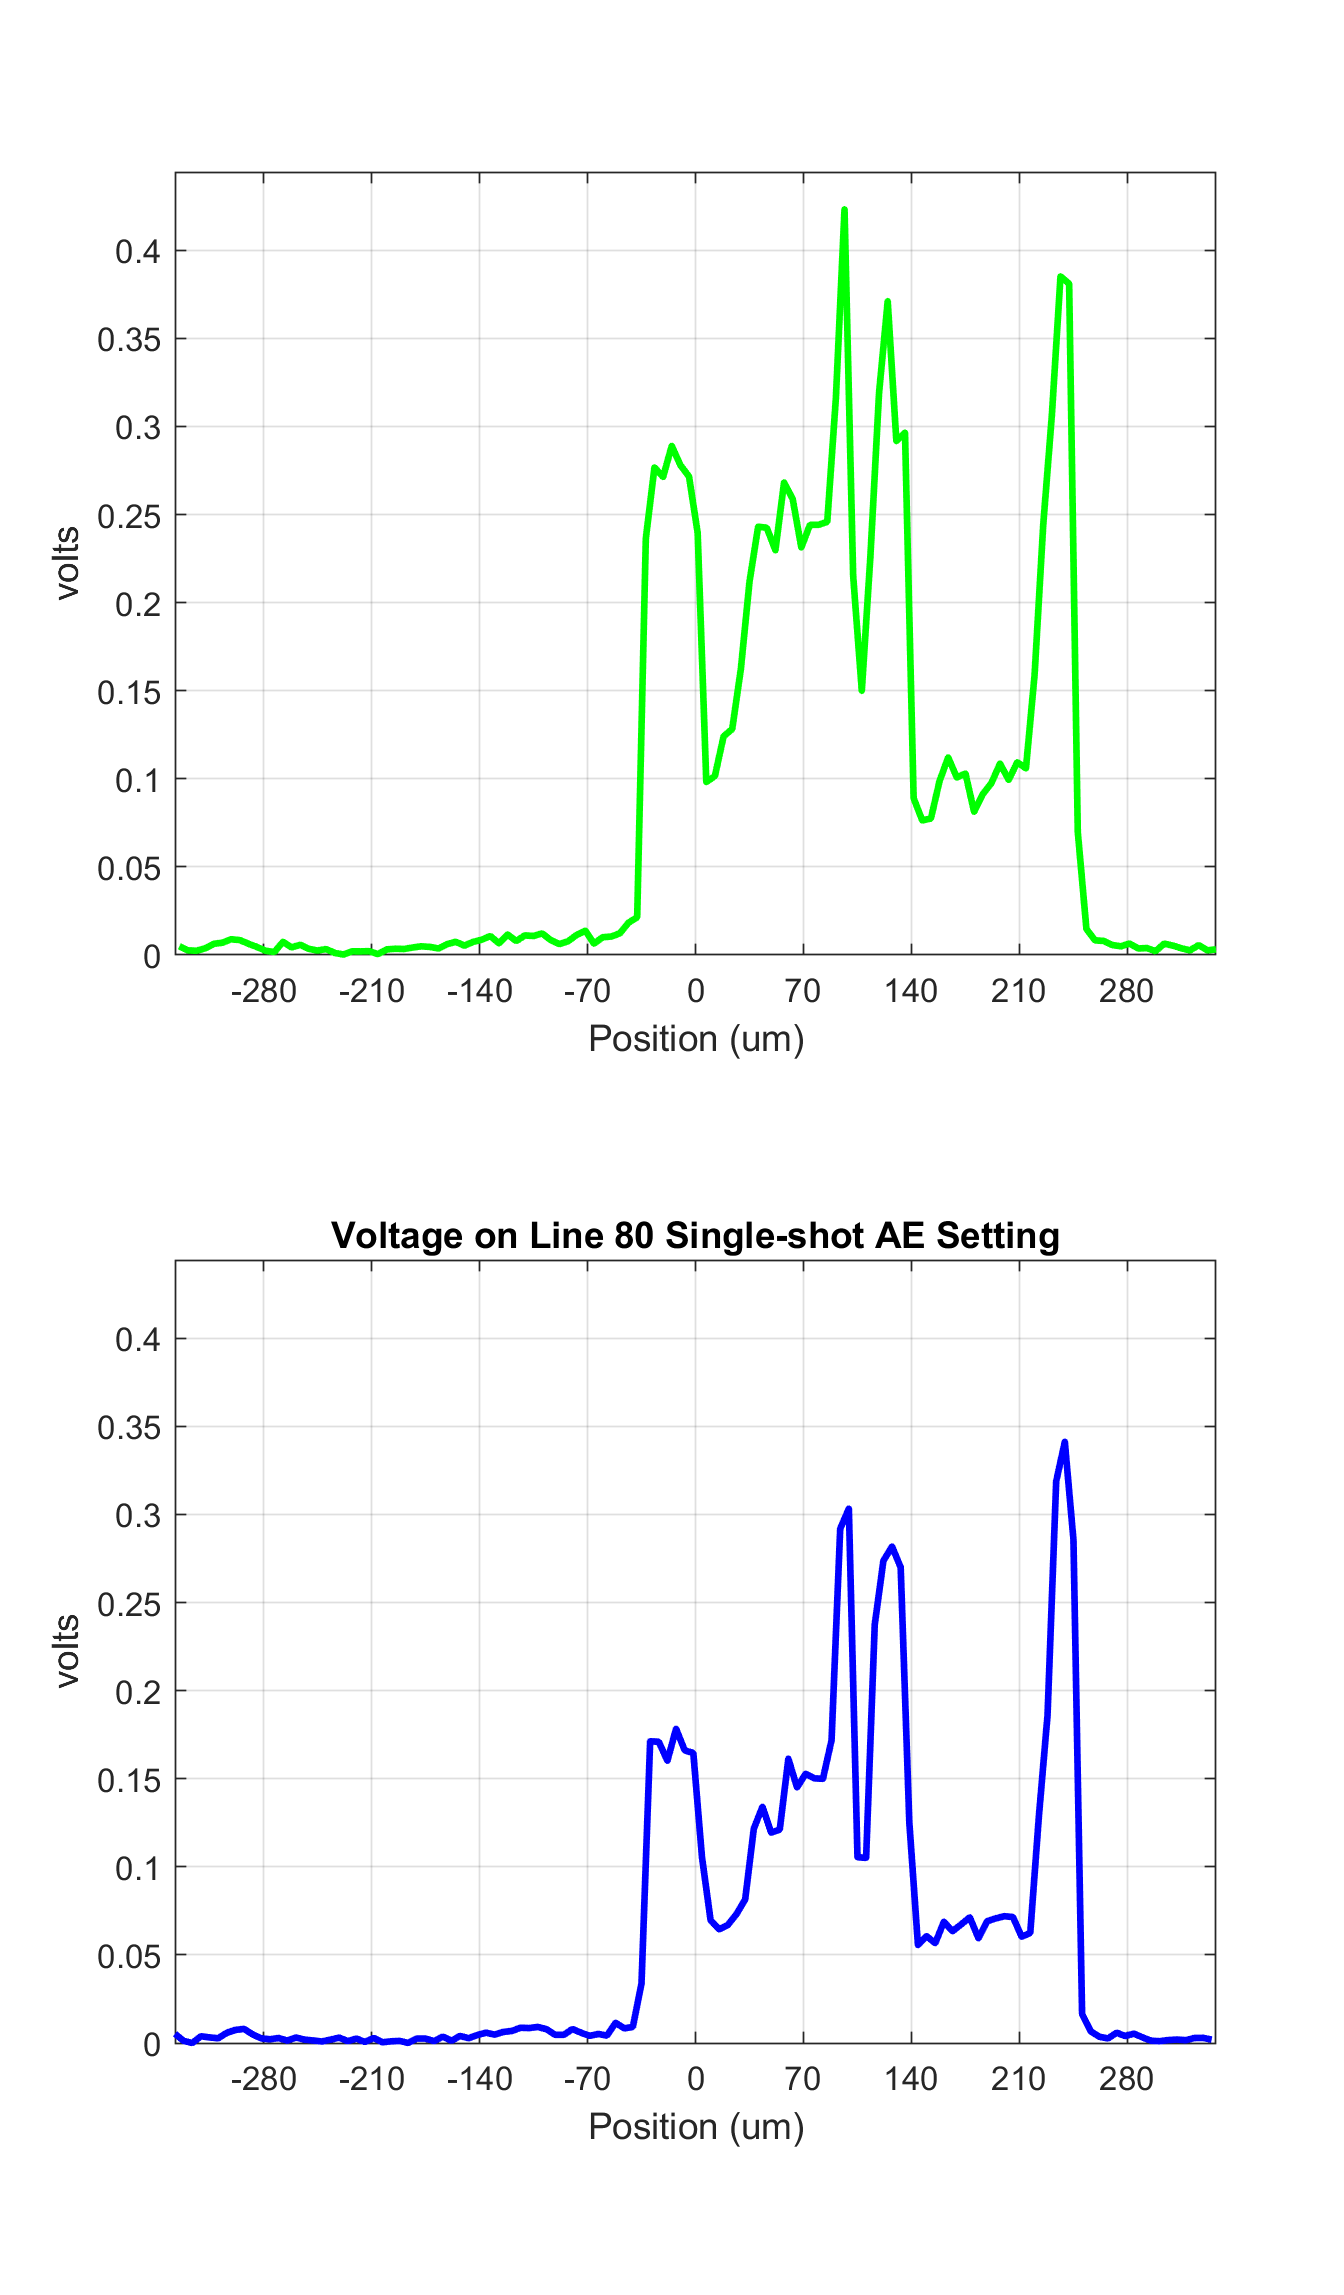

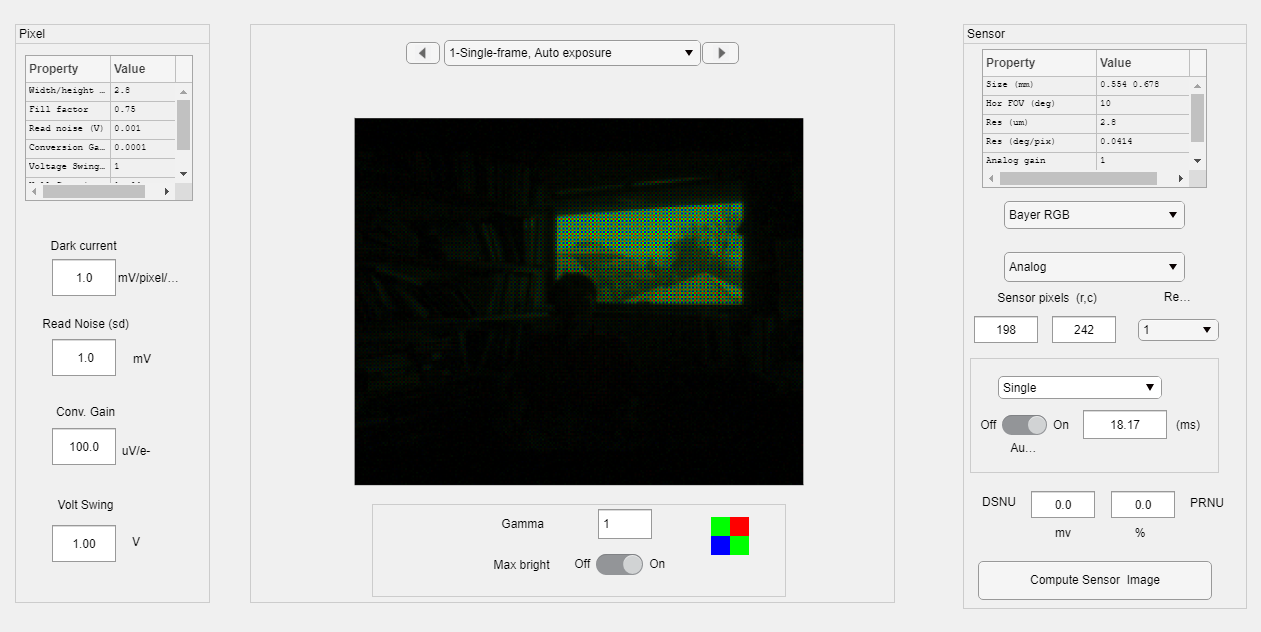

sensorPlot(sensorAE,'volts hline',[1,showLine]);
title(['Voltage on Line ', num2str(showLine), ' Single-shot AE Setting']);
sensorWindow(sensorAE);


% we do this after the AE version to change the burst gamma?
%sensorSet(sensor,'gamma',0.3);

### Now operate the sensor in burst mode

We'll experiment with the default noise setting, and then turn off all the sensor noise.

Use the slider to control how many images to take in a burst.

numImages     = 8 % Select # of images in a burst

numImages = 8

% Set exposure time so sum of the burst images gives us a total
% exposure time equal to the Auto-Exposure calculation:
expTime     = autoExposure(oi,sensor)/numImages; 
burstTiming = repmat(expTime,1,numImages);

sensorBurst = sensorSet(sensor,'exp time',burstTiming);

sensorBurst = sensorSet(sensorBurst,'noise flag','nophoton'); 
sensorBurst = sensorSet(sensorBurst,'name',sprintf('burst-default-noise-%d-frames',numel(burstTiming)));
sensorBurst = sensorCompute(sensorBurst,oi);
% sensorWindow(sensorBurst);
% v = sensorGet(sensorBurst,'volts');
% ieNewGraphWin; plot(squeeze(v(134,:,3)));

### Now build a low-noise version of the sensor:

sensorBurstLN = sensorSet(sensor,'exp time',burstTiming);
% hack to test if noise = -1 is now broken:
sensorBurstLN = sensorSet(sensorBurstLN,'noise flag',1); % turn sensor noise off
sensorBurstLN = sensorSet(sensorBurstLN,'name',sprintf('burst-low-noise-%d-frames',numel(burstTiming)));
sensorBurstLN = sensorCompute(sensorBurstLN, oi);
sensorBurstLN = sensorSet(sensorBurstLN,'exp time',burstTiming(1));

### Calculate the sensor images for our burst sensors:

Currently we simply average the voltage from each image capture of our default noise and low-noise burst sensors, and then multiply by the number of images to get back to a total exposure equal to a single AE frame:

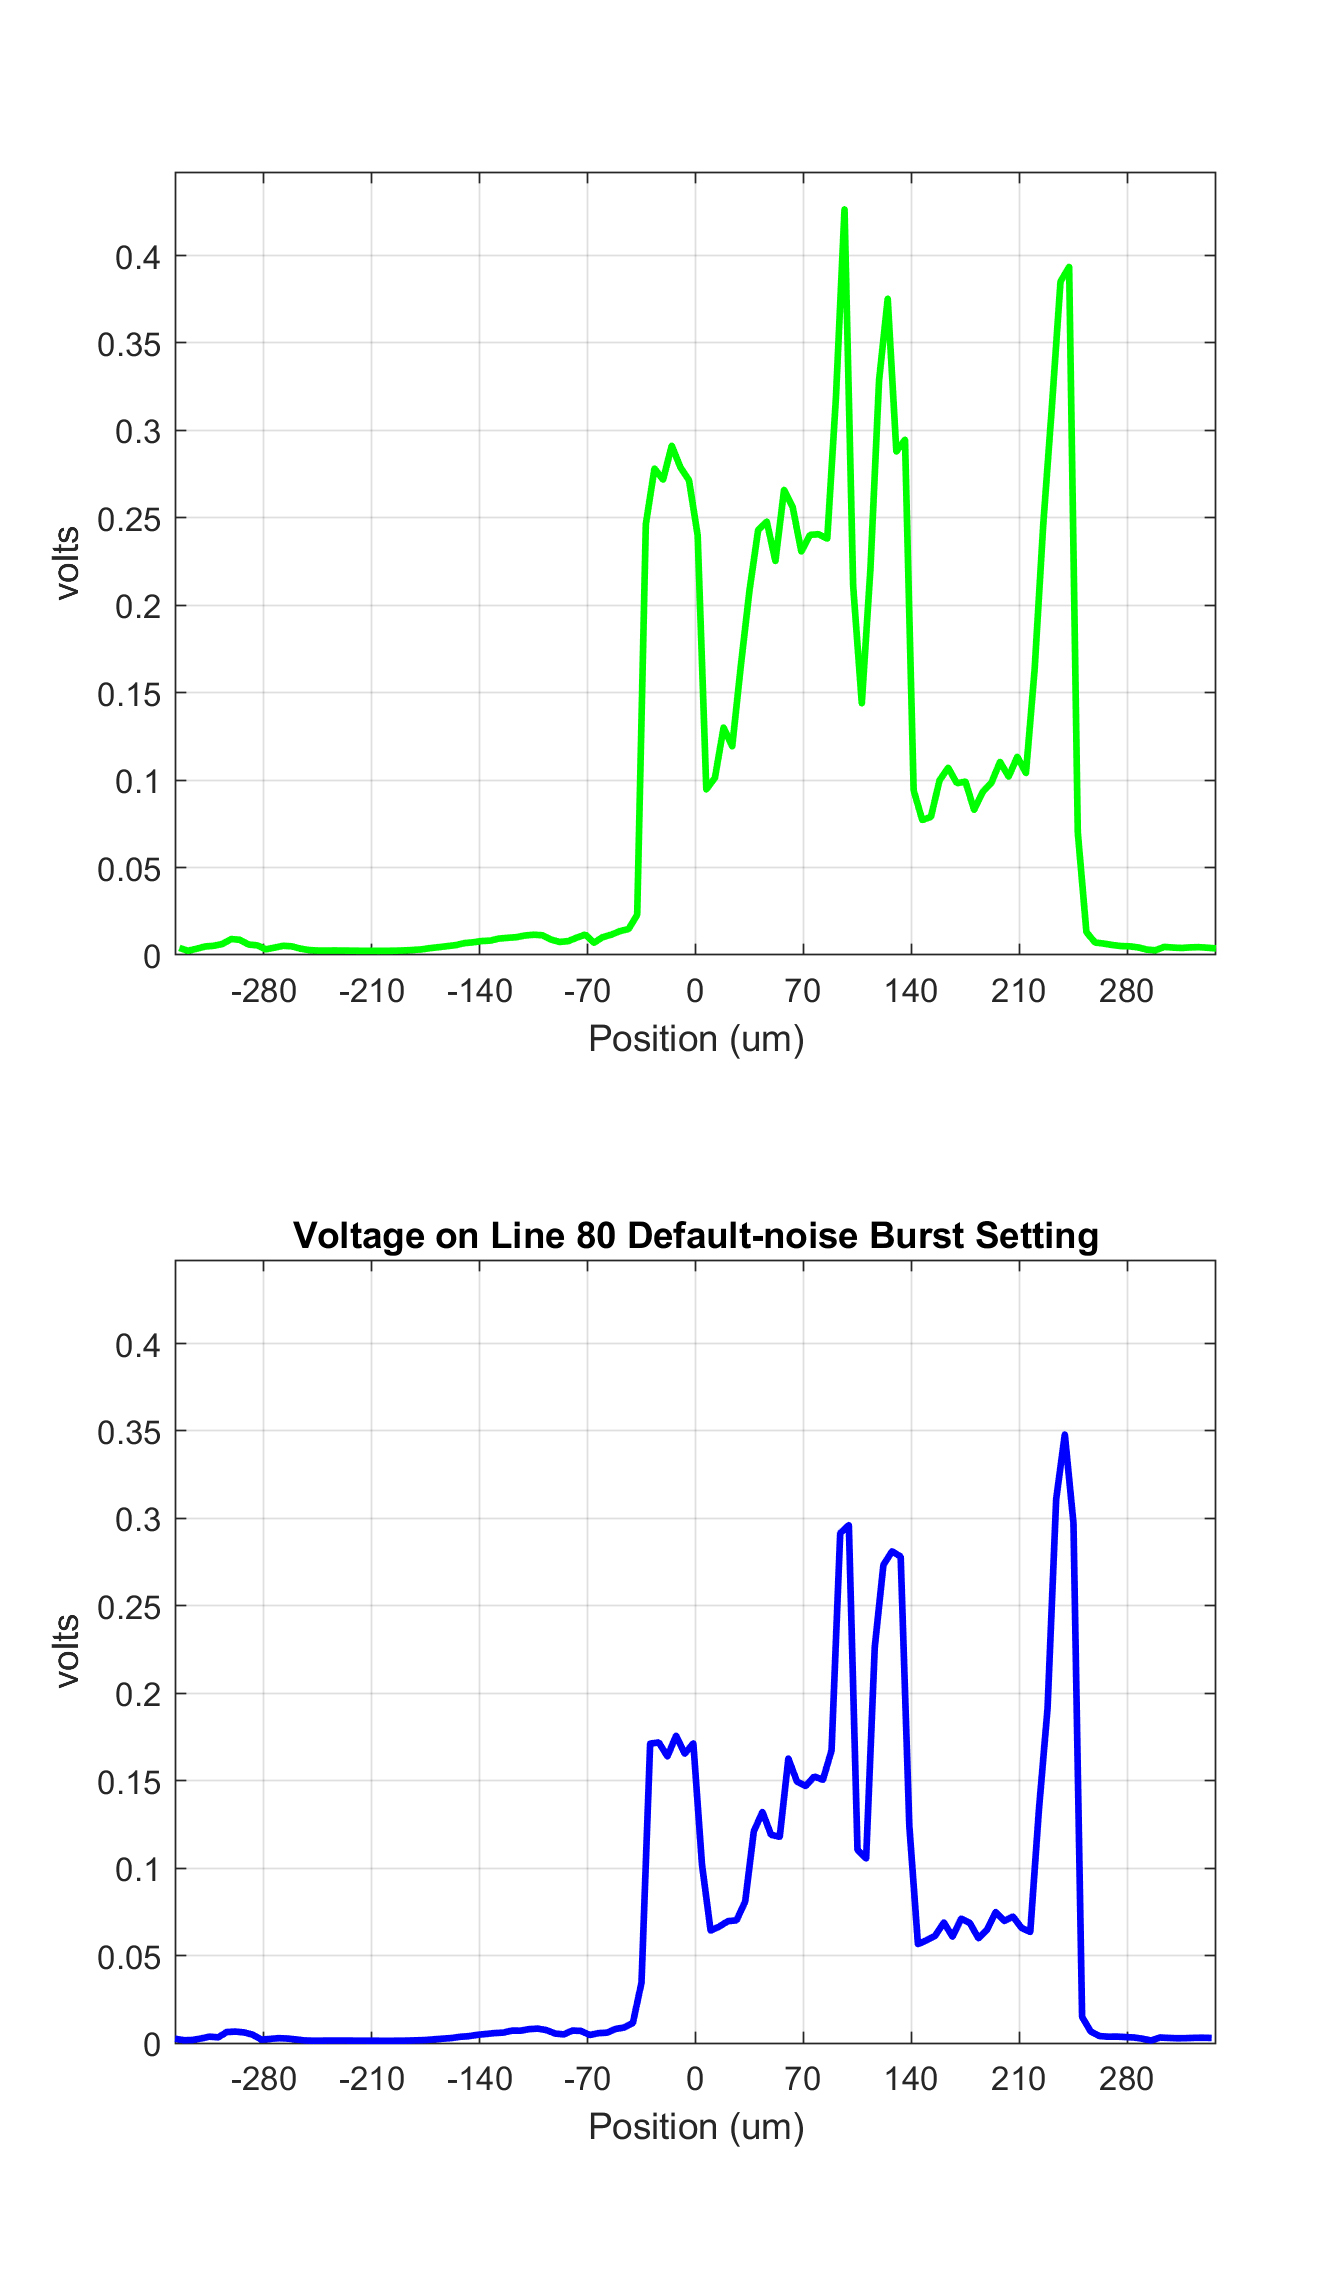

voltsBurst = sensorGet(sensorBurst, 'volts');
voltsBurst = sum(voltsBurst,3);
% By adding up the bursts, we effectively have only 1 exp time
sensorBurstSum = sensorSet(sensorBurst,'exp time',burstTiming(1)*numImages); 
sensorBurstSum = sensorSet(sensorBurstSum,'volts',voltsBurst);
sensorWindow(sensorBurstSum);

% Line is (x,y), not row,col.  (1,1) is upper left corner.
sensorPlot(sensorBurstSum,'volts hline',[1,showLine]);
title(['Voltage on Line ', num2str(showLine), ' Default-noise Burst Setting']);

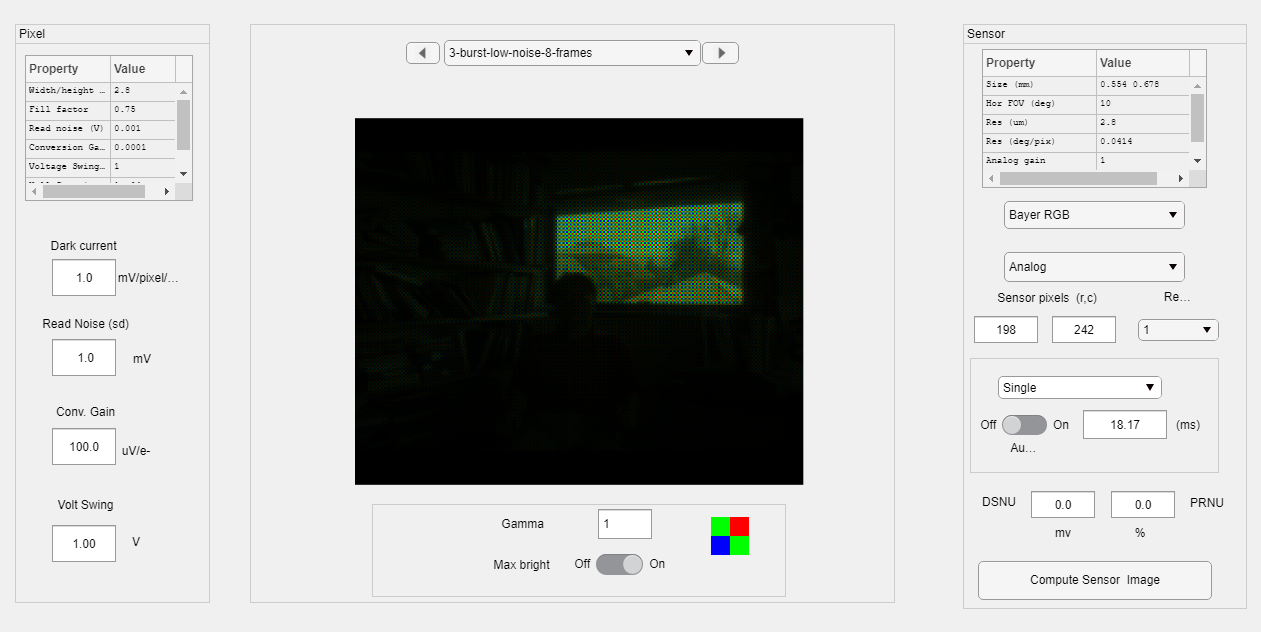

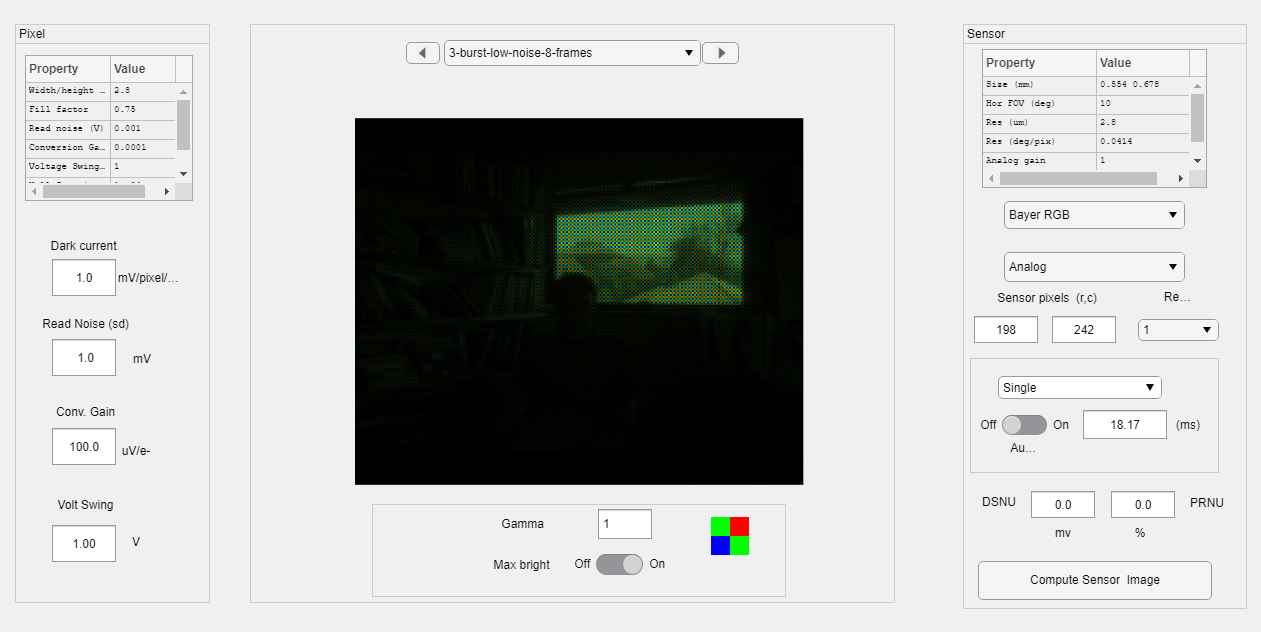


voltsLN = sensorGet(sensorBurstLN,'volts');
voltsLN = sum(voltsLN,3);
sensorBurstLNSum = sensorSet(sensorBurstLN,'volts',voltsLN);
sensorBurstLNSum = sensorSet(sensorBurstLNSum,'exp time',burstTiming(1)*numImages); 

sensorWindow(sensorBurstLNSum);

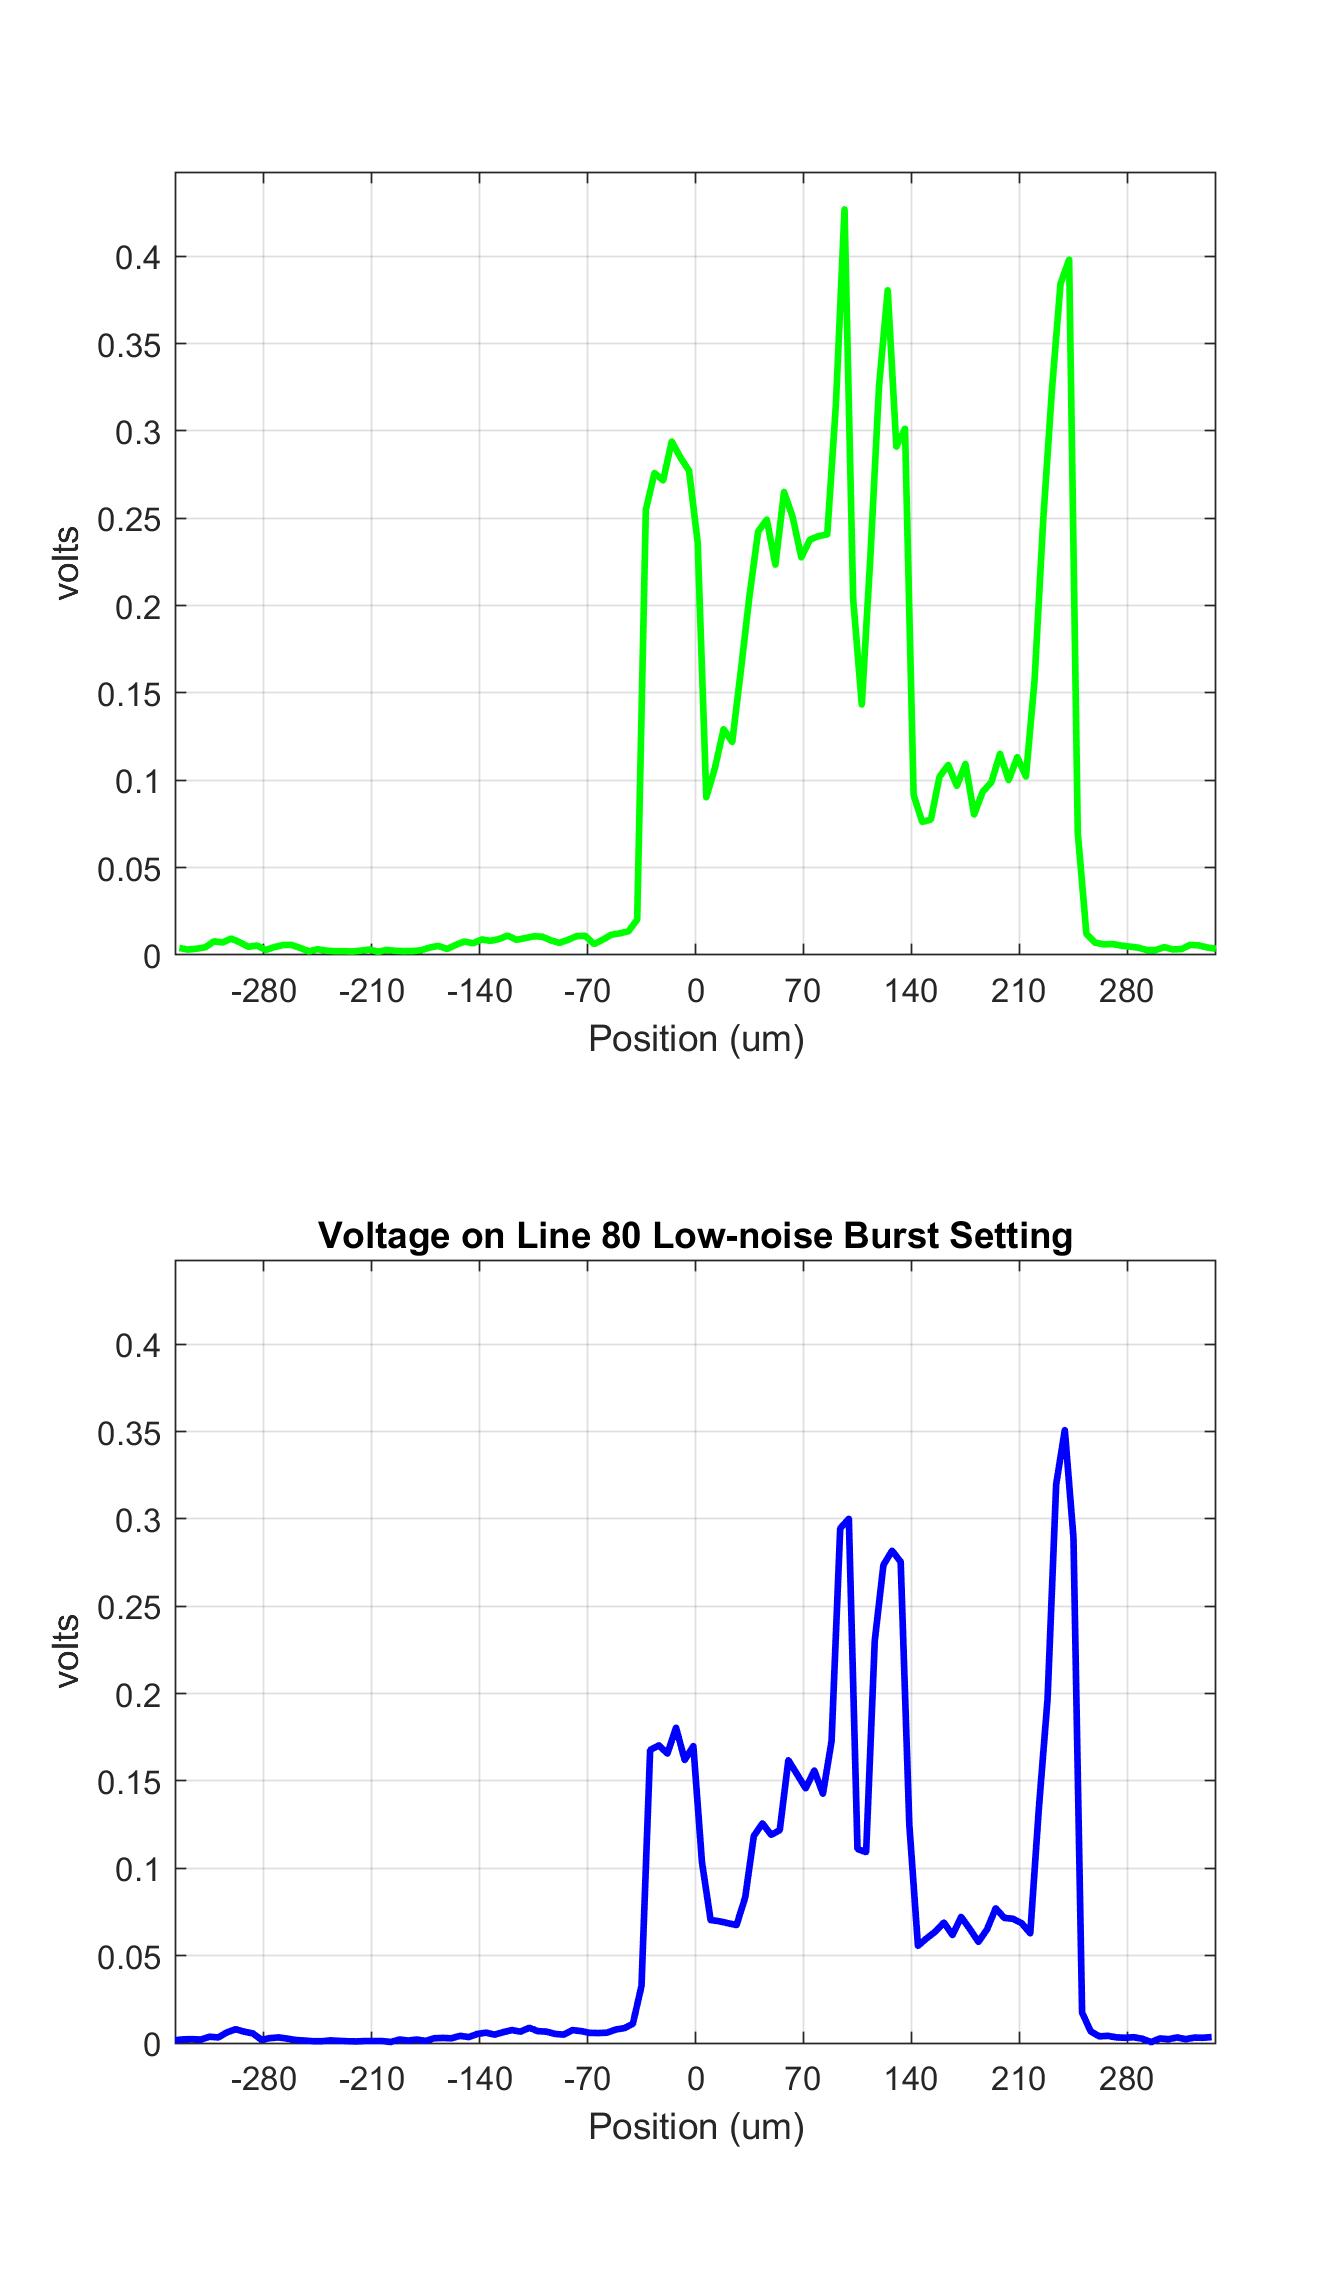


% Line is (x,y), not row,col.  (1,1) is upper left corner.
sensorPlot(sensorBurstLNSum,'volts hline',[1,showLine]);
title(['Voltage on Line ', num2str(showLine), ' Low-noise Burst Setting']);

## Process our Images

We use the same imaging pipeline (ip) for all three sensor versions (single-shot AE, Default-noise model Burst, and Low-Noise Burst). Note that because this is a Live Script, the graphs and thumbnails of the full Windows will show up on the right, with the interactive Windows being displayed separately.

AE Single Exposure


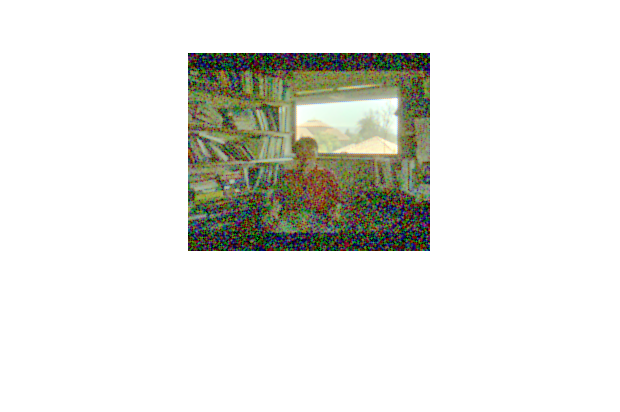

ip = ipCreate;
ip = ipSet(ip, 'render demosaic only', 'true');
ip = ipCompute(ip, sensorAE);
if hdrScene
    rgb = ipGet(ip, 'srgb');
    rgb = hdrRender(rgb);
    aeWin = ieNewGraphWin;
    aeWin.Name = 'AE Single Exposure';
    fprintf("AE Single Exposure\n");
    imagescRGB(rgb);
end

ipWindow(ip); 


ipBurst  = ipCreate;
ipBurst = ipSet(ipBurst, 'render demosaic only', 'true');
ipBurst  = ipCompute(ipBurst,sensorBurst);
if hdrScene
    rgbBurst = ipGet(ipBurst,'srgb');
    rgbBurst = hdrRender(rgbBurst);
    burstWin = ieNewGraphWin;
    burstWin.Name = 'Burst with Default Noise';
    fprintf("Burst with Default Noise\n");
    imagescRGB(rgbBurst);
end

Burst with Default Noise


Burst with Low Noise


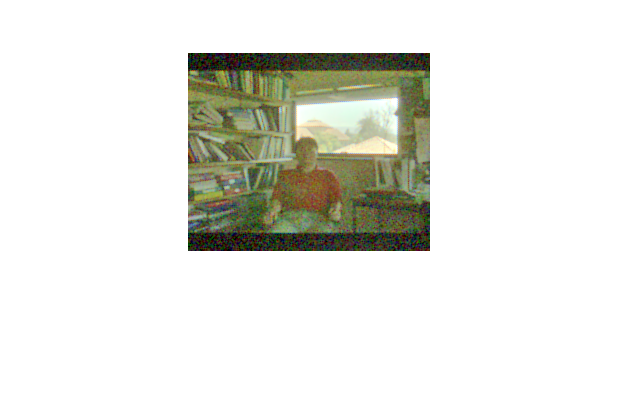

ipWindow(ipBurst);  

ipLN  = ipCreate;
ipLN = ipSet(ipLN, 'render demosaic only', 'true');
ipLN  = ipCompute(ipLN,sensorBurstLNSum);
if hdrScene
    rgbLN = ipGet(ipLN,'srgb');
    rgbLN = hdrRender(rgbLN);
    lnWin = ieNewGraphWin;
    lnWin.Name = 'Burst with Low Noise';
    fprintf("Burst with Low Noise\n");
    imagescRGB(rgbLN);
end

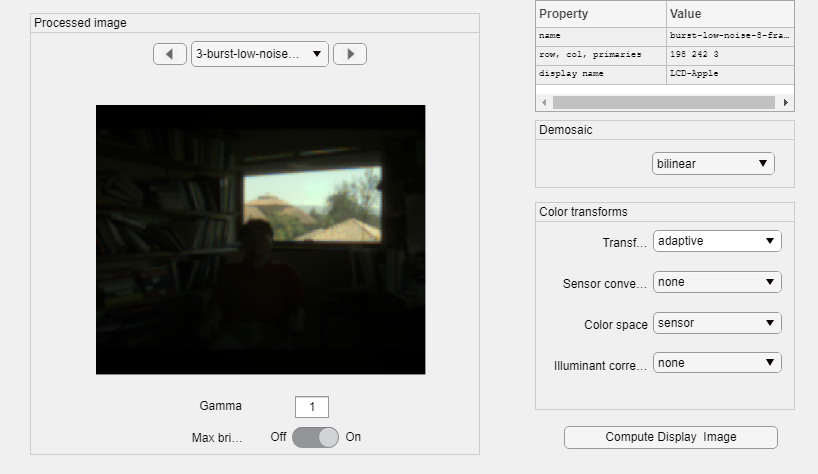

ipWindow(ipLN);  

### Experiment with Bracketing Exposures

Traditional "HDR" photography typically involves capturing a sequence of imges using exposures both below and above the normal "AutoExposure" value. Those images can be combined in camera or in post processing using a variety of algorithms to achieve the desired result.

The simplest way to combine the images -- that we use here -- is to use the largest non-saturated value at each pixel to create the finished photo. Intuitively you might think that more images and a wider range of bracketing are always better. However, depending on the quality of the sensor in use, noise can become an issue.

Here we let you experiment with how far apart exposures should be, and how many to capture. For whatever value of the number of images you set, we capture half above the AE value, and half below, with one frame at AE. The captures are spaced evenly apart by the number of f-Stops (powers of two) in exposure value you set for bracketStops.

You can also see how noise affects the process by turning sensor noise off and on. However, simply bracketing doesn't provide a smarter rendering of an HDR scene. That requires some type of tone mapping like that done by the hdrrender command.

% Set exposure time
expTimeHDR     = autoExposure(oi,sensor); 
numHDRImages = 9; % too high and we are dominated by noise, I think
bracketStops = 1.998

bracketStops = 1.9980

sensorNoise = true;
% Figure out how many images to bracket above and below
if ~isodd(numHDRImages)
    hdrImages = numHDRImages/2;
else
    hdrImages = (numHDRImages-1)/2;
end

% set our bracket timing array
hdrTiming = expTimeHDR*((2*(1+bracketStops)).^(-1*hdrImages:hdrImages));

sensorHDR = sensorSet(sensor,'exp time',hdrTiming);
if sensorNoise ~= 0
    sensorSet(sensorHDR,'Noise Flag',2);
else
    sensorSet(sensorHDR,'Noise Flag', -1);
end
sensorHDR = sensorSet(sensorHDR,'name',sprintf('burst-HDR-%d-frames',numel(hdrTiming)));
sensorHDR = sensorCompute(sensorHDR,oi);
% can't set sensor time back because we need it for bracketing!
%sensorHDR = sensorSet(sensorHDR,'exp time',hdrTiming(hdrImages + 1)); % set back


Unlike with equal exposures, bracketed images require some additional processing to decide which exposure to use for each pixel. Here we call a simple algorithm that uses the pixel readout from the longest exposure that doesn't saturate the pixel for each pixel:

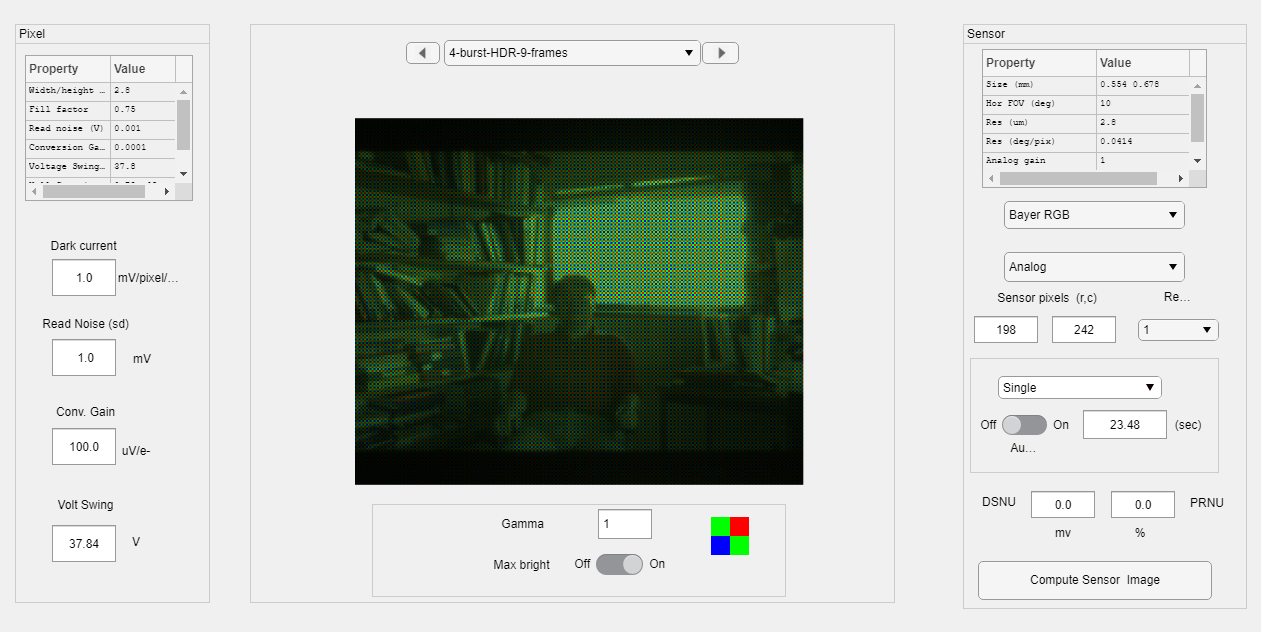

sensorHDR = sensorComputeMEV(sensorHDR, oi);
% ComputeMEV changes the sensor name, so we'll change it back
sensorHDR = sensorSet(sensorHDR,'name',sprintf('burst-HDR-%d-frames',numel(hdrTiming)));
voltsHDR = sensorGet(sensorHDR, 'volts');

sensorWindow(sensorHDR);

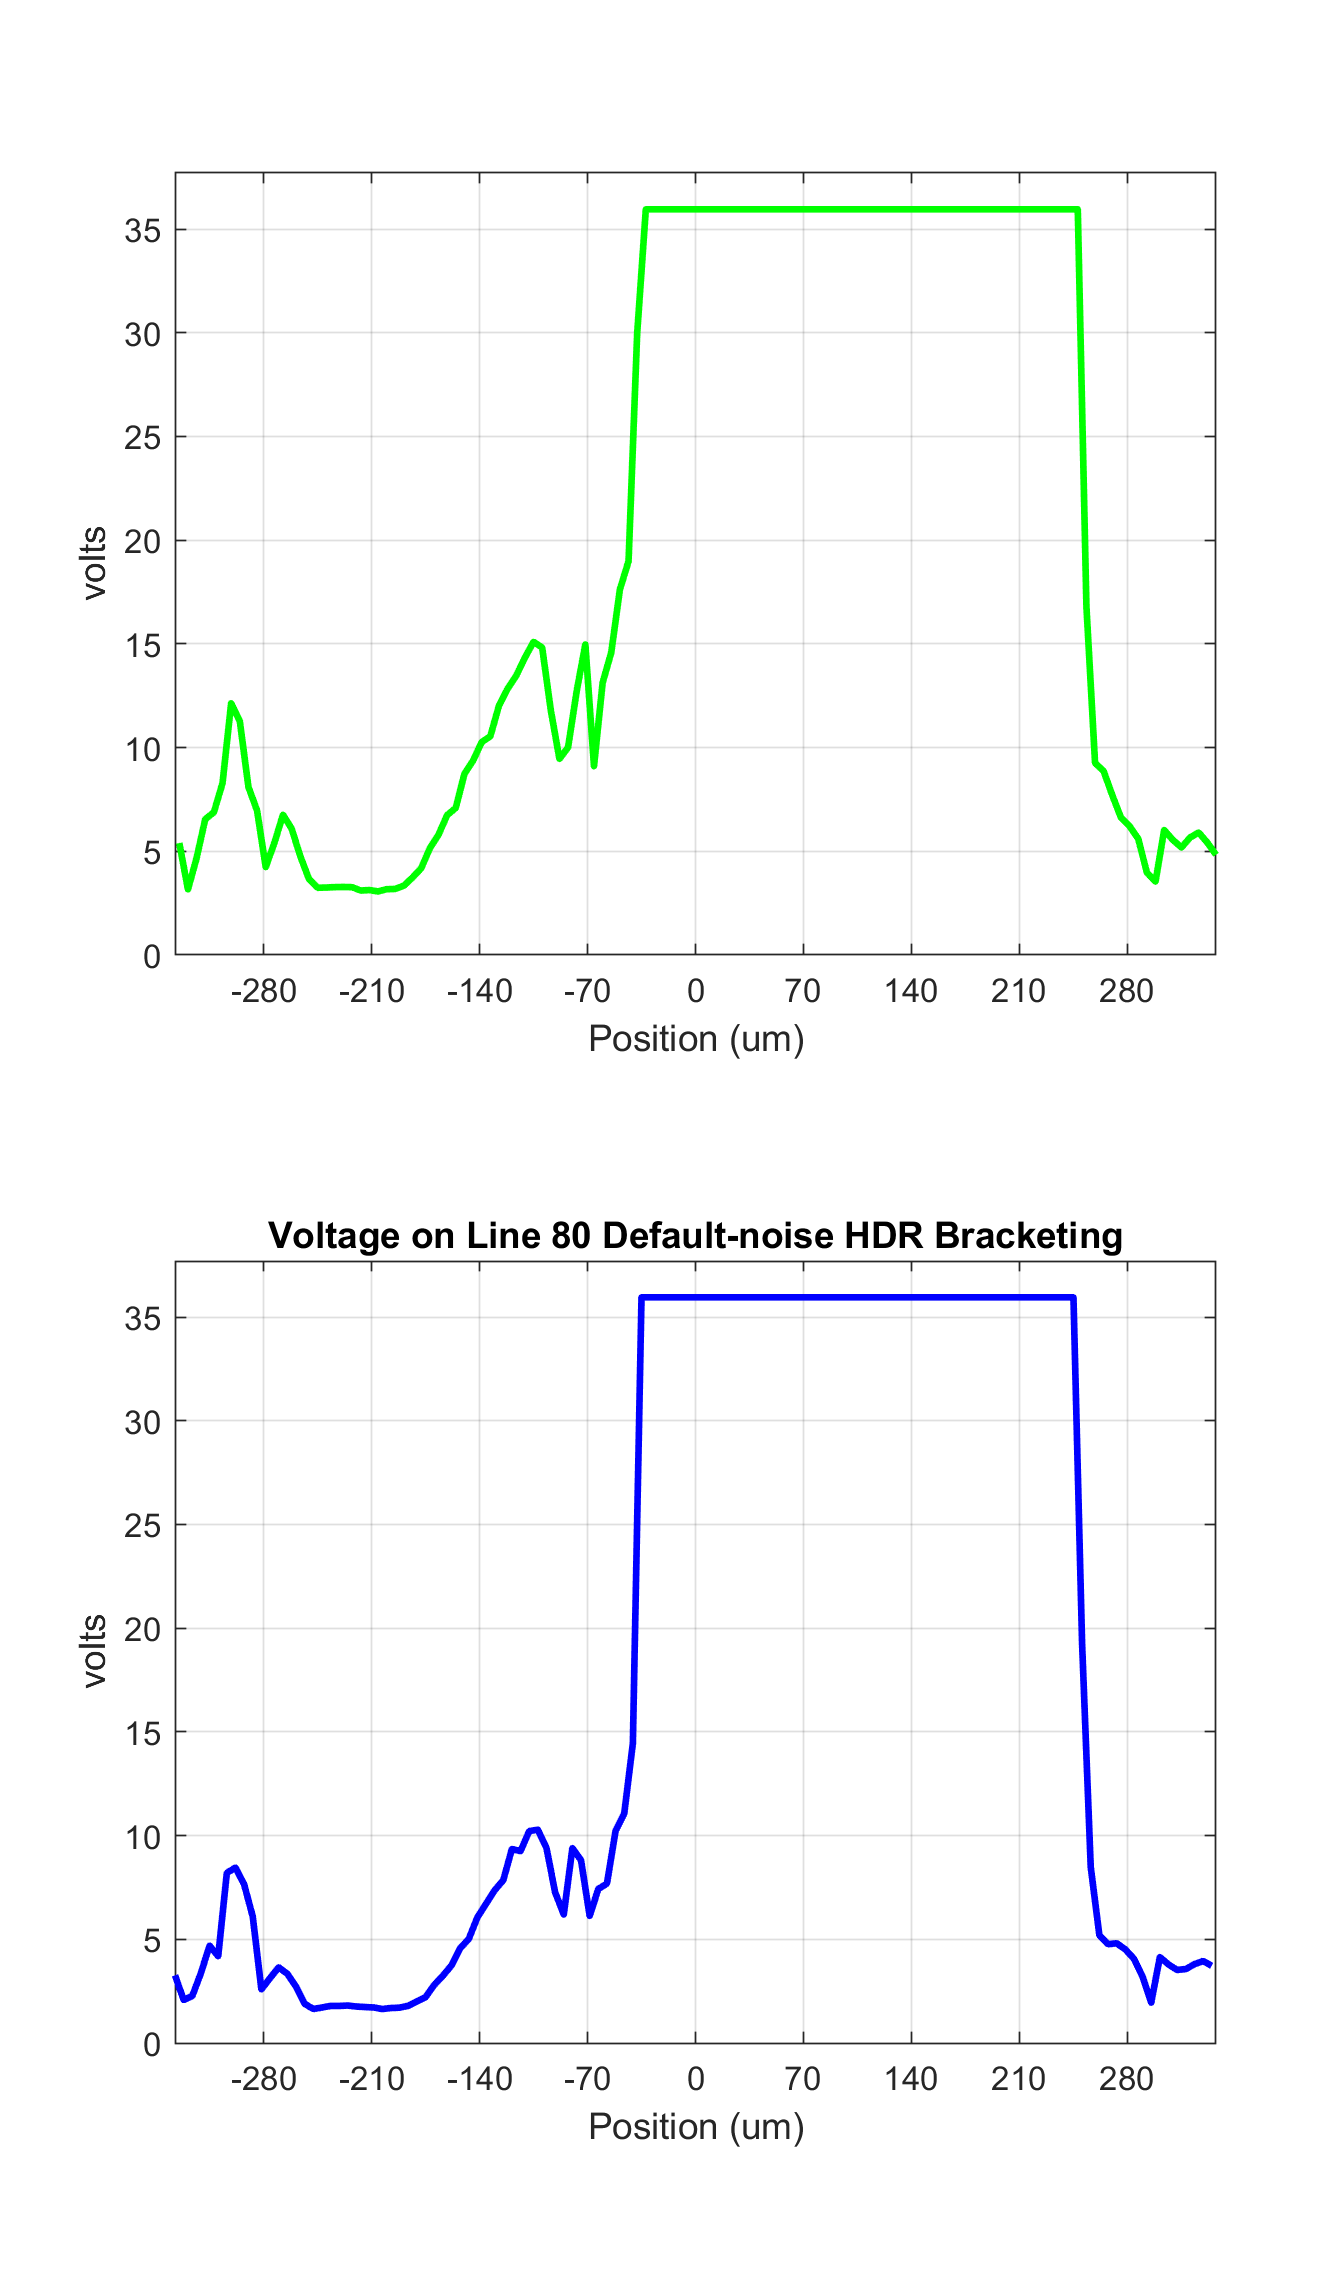


% Line is (x,y), not row,col.  (1,1) is upper left corner.
sensorPlot(sensorHDR,'volts hline',[1,showLine]);
title(['Voltage on Line ', num2str(showLine), ' Default-noise HDR Bracketing']);

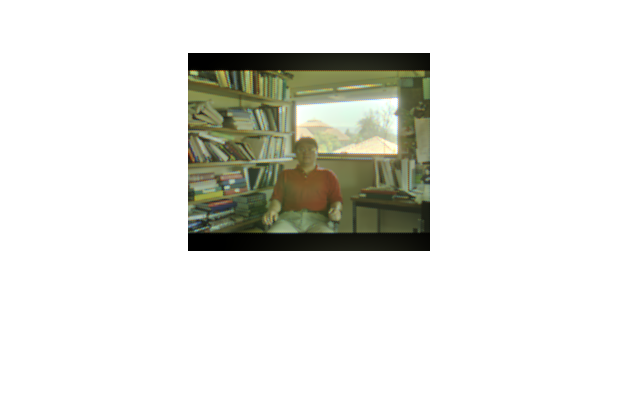

Bracketing with Default Noise


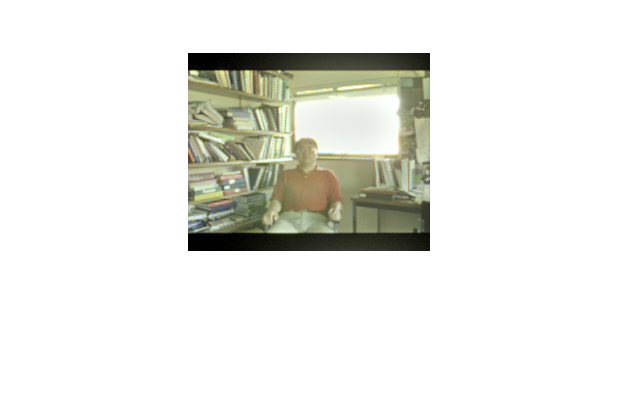


ipHDR  = ipCreate;
ipHDR = ipSet(ipHDR, 'render demosaic only', 'true');
ipHDR  = ipCompute(ipHDR,sensorHDR);
if hdrScene
    rgbHDR = ipGet(ipHDR,'srgb');
    rgbHDR = hdrRender(rgbHDR);
    burstHDR = ieNewGraphWin;
    burstWin.Name = 'Bracketing with Default Noise';
    fprintf("Bracketing with Default Noise\n");
    imagescRGB(rgbHDR);
end

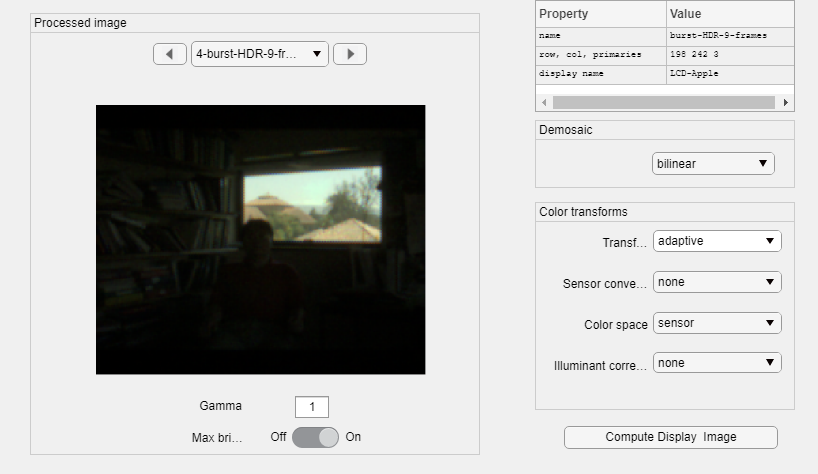

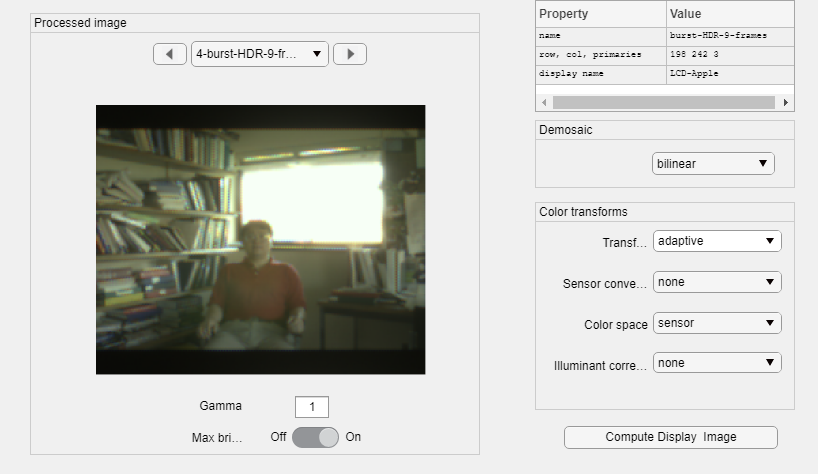

ipWindow(ipHDR);  


% Wonder if we still need this in Matlab 2020??
ieSessionSet('waitbar',wbState);  % Dealing with a waitbar/Matlab issue.